# Solving the Heat Equation for 1-D Conduction Through a Wall

### By: Arnaldo Rodriguez-Gonzalez

Consider a wall with a thickness of 1 meter, with no internal heat generation and such that heat transfer occurs only in one direction; through the wall. Defining a coordinate $x$ such that $x = 0$ on the left side of the wall and $x = 1$ on the right side of the wall, the simplified form of the heat equation that governs how the temperature changes in the wall over space and time is the following partial differential equation:


$$\frac{\partial \;T}{\partial \;t}=\alpha \frac{\partial^2 T}{\partial x^2 }\ldotp$$


The equation is defined on the interval $0\le x\le 1$ for times $t\ge 0$. At $t=0$, the solution satisfies the initial condition


$$T\left(x,0\right)=T_0 \ldotp$$


where $T_0$, the initial uniform temperature of the wall, can be set on the sliders. 

Also, at either edge of the wall ($x=0$ and $x=1$), the solution can satisfy some combination of 2 of the boundary conditions listed below. All ${q^{\prime } }^{\prime }$ below are defined such that they are positive when thermal energy is flowing to the right, i.e. in the $\hat{x}$ direction.


$$T\left(0,t\right)=T_L ,$$



$$T\left(0,t\right)=T_R ,$$



$${q^{\prime } }^{\prime } \left(0,t\right)=-k\frac{\partial T}{\partial x}\left(0,t\right)={q^{\prime } }_L^{\prime }$$



$${q^{\prime } }^{\prime } \left(1,t\right)=-k\frac{\partial T}{\partial x}\left(1,t\right)={q^{\prime } }_R^{\prime }$$



$${q^{\prime } }^{\prime } \left(0,t\right)=-k\frac{\partial T}{\partial x}\left(0,t\right)=h\left(T_{{\textrm{surr}}_L \;} -T\left(0,t\right)\right)$$



$${q^{\prime } }^{\prime } \left(1,t\right)=-k\frac{\partial T}{\partial x}\left(1,t\right)=h\left(T\left(L,t\right)-T_{{\textrm{surr}}_R \;} \right)$$


Selecting any two of these boundary conditions and their associated values, which you can do using the selection boxes, fully determines the temperature distribution inside of the wall for all positive time.

## Selecting Parameter Values, Initial Condition and Boundary Conditions

Use the various inputs below to select the parameter values and boundary conditions for the wall problem. Note that selecting parameters associated with a boundary conditions you are not using will not affect the solution of the problem.

chL = 3;
chR = 3;
tscale = 1;
alpha = 0.3;
k = 0.1;
h = 5;
T0 =10;
TL = 4.5;
TR = 3;
TsurrL = 5;
TsurrR = 5;
qdpl = 1;
qdpr = 0;

All heat fluxes are defined here to be positive when thermal energy flows in the direction of increasing $x$.

x = linspace(0,1,1000);
t = linspace(0,tscale,1000);
m = 0;
sol = pdepe(m,@(x,t,u,dudx)pdex1pde(x,t,u,dudx,alpha),@(x)pdex1ic(x,T0),@(xl,ul,xr,ur,t)pdex1bc(xl,ul,xr,ur,t,chL,chR,TL,TR,TsurrL,TsurrR,qdpl,qdpr,k,h),x,t);
u = sol(:,:,1);
umx = max(max(u));
umn = min(min(u));

## Solution

After pressing the button above, the simulation animates the solution of the heat equation—the temperature profile in the wall as it evolves over time. It will play an animation that might be a bit laggy depending on your computer specs; but after the animation is finished playing, you will have the ability to play it again without much lag using a playback bar below the animation, or you can even export the animation into a GIF or video.

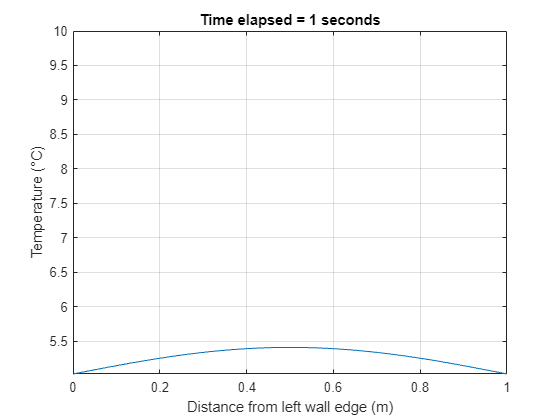

dataplaceholder = plot(x,u(:,1));
plotplaceholder = gca;
xlabel('Distance from left wall edge (m)')
ylabel('Temperature (°C)')
grid on
dataplaceholder.XData = x;
xlim([0 1])
ylim([umn umx])
tic
for counter = 1:1:1000
    dataplaceholder.YData = u(counter,:);
    plotplaceholder.Title.String = "Time elapsed = "+ (tscale/1000)*counter +" seconds";
    pause(0.02)
end

## Things to Think About

- Apply a convective boundary condition on either side of the wall, and ensure the surroundings temperature on either side of the wall is the same. Feel free to set the initial temperature in the wall to anything that isn't the temperature of the surroundings. Compare how the temperature in the wall varies in space when a) the Biot number is 0.01 and b) the Biot number is 100.

- Select the constant temperature boundary conditions on either side of the wall, and choose all three relevant temperatures (the two boundary temperatures and the initial temperature) to be different. How would you describe the behavior of the temperature distribution over time?

- Select the constant heat flux conditions on either side of the wall, and choose the fluxes to be different. What do you notice about how the temperature distribution changes over time? Compare that to a case where one side of the wall has a constant temperature condition and the other has a constant heat flux. How do you explain those differences?

- In the dimensionless form of the heat equation, it's common to represent a "dimensionless time" $t^* = t \frac{\alpha}{L_c^2}$, where $\alpha$ is the thermal diffusivity, $L_c$ is the characteristic length of this system (the wall thickness) and $\frac{L_c^2}{\alpha}$ can be interpreted to play the role of an effective time constant. Try altering the value of the thermal diffusivity to confirm or refute whether or not this interpretation of $\frac{L_c^2}{\alpha}$ makes sense.

- Place a constant temperature boundary condition on one side of the wall and an adiabatic (zero heat flux) boundary condition on the other side. Use whatever parameters you like. What do you think the temperature distribution in the wall should be? Simulate this scenario, and confirm/refute your hypothesis.

- Using a constant heat flux boundary condition on the left-hand side of the wall and a constant temperature boundary condition on the right-hand side of the wall, find parameter values such that at steady-state, $T(x,t\to\infty) = 5 - 2x$.

function [c,f,s] = pdex1pde(x,t,u,dudx,alpha) % Equation to solve
c = 1/alpha;
f = dudx;
s = 0;
end
%----------------------------------------------
function u0 = pdex1ic(x,T0) % Initial conditions
u0 = T0;
end
%----------------------------------------------
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t,chL,chR,TL,TR,TsurrL,TsurrR,qdpl,qdpr,k,h) % Boundary conditions
if chL == 1
    pl = ul - TL;
    ql = 0;
elseif chL == 2
    pl = qdpl;
    ql = k;
elseif chL == 3
    pl = h*(TsurrL - ul);
    ql = k;
end
if chR == 1
    pr = ur - TR;
    qr = 0;
elseif chR == 2
    pr = qdpr;
    qr = k;
elseif chR == 3
    pr = h*(ur - TsurrR);
    qr = k;
end
end
%----------------------------------------------